# Immunometabolism Differential Reaction Sensitivity Analysis

**Author:** Scott Campit

## Summary

This script computes differentially sensitive reactions resulting from reaction knockouts in the metabolic reconstruction.

clear all;

### RECON1

% LOAD RECON1 Results
%load D:\Analysis\Immune\param_sense_soln_1E-6_rho.mat

### iHUMAN

% LOAD iHUMAN Results
load D:\Analysis\Immune\iHUMAN_PSA.mat;

## Knockout analysis

This code block analyzes the relative change between time points from the knockout results. **Currently, this is only performed in RECON1** - if you're doing the iHUMAN modeling, you should skip this section for now.

### Rho perturbation

The following codeblock analyzes the Rho perturbation analysis.

#### Construct the control matrix

for i = 1:length(allRhoCntrRxn)
    cntrl_rho_rxn(:, i)   = allRhoCntrRxn{i};
end

#### Make DRSA matrices

Currently, each treatment KO is nested in a separate cell array within another container. Let's do a partial un-nesting, where all data will still be stored in cell arrays, but will be converted to numeric for each individual cell.

rho_drsa = cell(10, 5);
for i = 1:length(allRhoRxnKO)
    rho_constraint = allRhoRxnKO{i};
    tmpCntrl                = cntrl_rho_rxn(:, i)  ./ median(cntrl_rho_rxn(:, i));
    for j = 1:length(rho_constraint)
        cell_type = rho_constraint{j};
        tmpRho = cell_type ./ median(cell_type);
        tx_rho_rxn = tmpRho ./ tmpCntrl;
        rho_drsa{j, i} = tx_rho_rxn; 
    end
end

#### Compute mean and standard deviation from data

The purpose of this code block is to get some value summary statistics that will help us select the best parameters to use for the metabolic model.

for i = 1:size(rho_drsa, 1)
    for j = 1:size(rho_drsa, 2)
        meanrhograte(i, j) = nanmean(rho_drsa{i, j}(isfinite(rho_drsa{i, j})), 'all');
        stdrhograte(i, j)  =  nanstd(rho_drsa{i, j}(isfinite(rho_drsa{i, j})), [], 'all');
    end
end

### Kappa perturbation

First, let's evaluate the rho perturbation data.

load D:\Analysis\Immune\param_sense_soln_1E-6_kappa.mat

We'll construct the control matrix

for i = 1:length(allKapCntrRxn)
    cntrl_kap_rxn(:, i)   = allKapCntrRxn{i};
end

#### Make DRSA matrices

Currently, each treatment KO is nested in a separate cell array within another container. Let's do a partial un-nesting, where all data will still be stored in cell arrays, but will be converted to numeric for each individual cell.

kap_drsa = cell(10, 5);
for i = 1:length(allKapRxnKO)
    kap_constraint = allKapRxnKO{i};
    tmpCntrl                = cntrl_kap_rxn(:, i)  ./ median(cntrl_kap_rxn(:, i));
    for j = 1:length(kap_constraint)
        cell_type = kap_constraint{j};
        tmpKap = cell_type ./ median(cell_type);
        tx_kap_rxn = tmpKap ./ tmpCntrl;
        kap_drsa{j, i} = tx_kap_rxn; 
    end
end

#### Compute mean and standard deviation from data

The purpose of this code block is to get some value summary statistics that will help us select the best parameters to use for the metabolic model.

for i = 1:size(kap_drsa, 1)
    for j = 1:size(kap_drsa, 2)
        meankapgrate(i, j) = nanmean(kap_drsa{i, j}(isfinite(kap_drsa{i, j})), 'all');
        stdkapgrate(i, j)  =  nanstd(kap_drsa{i, j}(isfinite(kap_drsa{i, j})), [], 'all');
    end
end

### Select the growth rate distribution to use

Based on the objective I used: choosing the minimum parameter that maximized the standard deviation of the growth rate distributions, I saw the the default parameters kappa and rho = 1 were the optimal distributions to analyze.

clear kap_drsa rho_drsa
kap_constraint = allKapRxnKO{3};
rho_constraint = allRhoRxnKO{3};
tmpCntrl                = cntrl_kap_rxn(:, 3)  ./ median(cntrl_kap_rxn(:, 3));
sanity_check = [];
for j = 1:length(kap_constraint)
    cell_type_kap = kap_constraint{j};
    cell_type_rho = rho_constraint{j};
    
    tmpKap = cell_type_kap ./ median(cell_type_kap);
    tmpRho = cell_type_rho ./ median(cell_type_rho);
    
    tx_kap_rxn = tmpKap ./ tmpCntrl;
    tx_rho_rxn = tmpRho ./ tmpCntrl;
    
    kap_drsa{j} = tx_kap_rxn; 
    rho_drsa{j} = tx_rho_rxn;
    
    % Check and see if there is any difference. I expect that there is no
    % diff.
    sanity_check(j) = nansum(kap_drsa{j} - rho_drsa{j}, 'all');
end
sanity_check

sanity_check =      0     0     0     0     0     0     0     0     0     0


### Make reaction identifiers

This will be the identifiers to use for mapping in the final excel sheet.

ids = [recon1.rxns, recon1.rxnNames, recon1.subSystems];

### Remove data points where all normalized growth rate fold change values > 0.99

We're only intereted in reactions that have a normalized growth rate fold change less than 0.99. This indicates that the reaction knockout was essential for the survival of the cell. 

% Growth rates
grate = {};
celltype_id = {};
for i = 1:length(kap_drsa)
    tmp_grate = kap_drsa{i};
    tmp_grate(isnan(tmp_grate)) = 1;
    tmp_grate(isinf(tmp_grate)) = 1;
    
    celltype_id{i} = ids;
    idx = any(tmp_grate <= 0.9999, 2);
    
    celltype_id{i}(~idx, :) = [];
    tmp_grate(~idx, :) = [];
    
    %try
    %    % Remove data points that contain all NaNs
    %    idx2 = all(isnan(tmp_grate), 2);
    %    
    %    celltype_id{i}(~idx2, :)  = [];
    %    tmp_grate(~idx2, :) = [];
    %catch ME
    %    tmp_grate = [];
    %end
    grate{i} = tmp_grate;
end

## Metabolic Flux Analysis

This code block looks at the metabolic fluxes instead of growth rates from reaction knockout. **To simplify this analysis, we can only look at the absolute fold change** - in other words, we will omit the directionality of the reaction flux changes.

### Rho perturbation

Note that when rho was set to be a really small value (1E-4), many flux solutions were not solvable. Thus, we will only analyze rho values ranging from 0.01 to 10 for 12 cell types.

allRhoFlux(1)  = [];
CntrRhoFlux(1) = [];

#### Get relative flux matrix

rho_drsa       = cell(12, 4);
for i = 1:length(allRhoFlux)
    % Grab constrained model and "Day 0"
    rho_constraint = allRhoFlux{i};
    cntrl_rho_rxn  = abs(CntrRhoFlux{i});
    cntrl_rho_rxn  = rescale(cntrl_rho_rxn);
    
    % Mean normalize Day 0
    tmpCntrl       = abs(cntrl_rho_rxn ./ abs(mean(cntrl_rho_rxn, 'omitnan')));
    
    % Iterate through each cell type
    for j = 1:length(rho_constraint)
        
        % Get absolute value of fluxes
        cell_type  = abs(rho_constraint{j});
        
        % Re-scale data
        for k = 1:size(cell_type, 2)
            cell_type(:, k)  = rescale(cell_type(:, k));
        end
        
        % Mean normalize data
        tmpRho     = cell_type ./ mean(cell_type, 'omitnan');
        
        % Get fold changes for each time transition
        d07d00 = tmpRho(:, 1) ./ (tmpCntrl     + 1E-3);
        d14d07 = tmpRho(:, 2) ./ (tmpRho(:, 1) + 1E-3);
        d21d14 = tmpRho(:, 3) ./ (tmpRho(:, 2) + 1E-3);
        
        % Transform to log scale
        tx_rho_rxn = [d07d00, d14d07, d21d14];
        tx_rho_rxn = log(tx_rho_rxn);
        tx_rho_rxn(tx_rho_rxn==-inf) = 0;
        
        % Store results in matrix
        rho_drsa{j, i} = tx_rho_rxn; 
    end
end

#### Visualize metabolic flux distribution

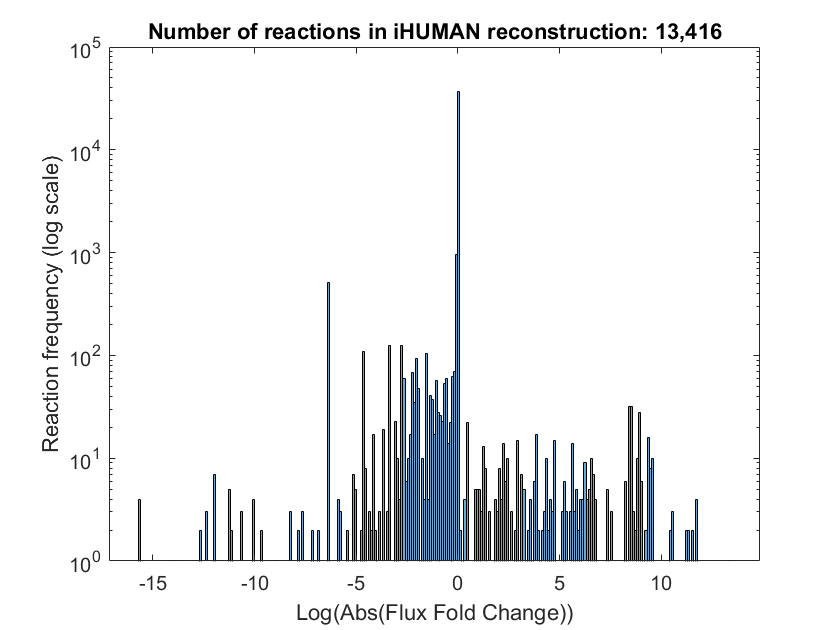

histogram(rho_drsa{12,4});
set(gca, 'YScale', 'log');
xlabel('Log(Abs(Flux Fold Change))');
ylabel('Reaction frequency (log scale)');
title('Number of reactions in iHUMAN reconstruction: 13,416');

#### Compute mean and standard deviation for model selection

for i = 1:size(rho_drsa, 1)
    for j = 1:size(rho_drsa, 2)
        meanRhoFlux(i, j) = nanmean(rho_drsa{i, j}(isfinite(rho_drsa{i, j})), 'all');
        stdRhoFlux(i, j)  =  nanstd(rho_drsa{i, j}(isfinite(rho_drsa{i, j})), [], 'all');
    end
end

### Kappa perturbation

#### Get relative flux matrix

kap_drsa       = cell(12, 5);
for i = 1:length(allKapFlux)
    % Grab constrained model and "Day 0"
    kap_constraint = allKapFlux{i};
    cntrl_kap_rxn  = abs(CntrKapFlux{i});
    cntrl_kap_rxn  = rescale(cntrl_kap_rxn);
    
    % Mean normalize Day 0
    tmpCntrl       = abs(cntrl_kap_rxn ./ abs(mean(cntrl_kap_rxn, 'omitnan')));
    
    % Iterate through each cell type
    for j = 1:length(kap_constraint)
        
        % Get absolute value of fluxes
        cell_type  = abs(kap_constraint{j});
        
        % Re-scale data
        for k = 1:size(cell_type, 2)
            cell_type(:, k)  = rescale(cell_type(:, k));
        end
        
        % Mean normalize data
        tmpKap     = cell_type ./ mean(cell_type, 'omitnan');
        
        % Get fold changes for each time transition
        d07d00 = tmpKap(:, 1) ./ (tmpCntrl     + 1E-3);
        d14d07 = tmpKap(:, 2) ./ (tmpKap(:, 1) + 1E-3);
        d21d14 = tmpKap(:, 3) ./ (tmpKap(:, 2) + 1E-3);
        
        % Transform to log scale
        tx_kap_rxn = [d07d00, d14d07, d21d14];
        tx_kap_rxn = log(tx_kap_rxn);
        tx_kap_rxn(tx_kap_rxn==-inf) = 0;
        
        % Store results in matrix
        kap_drsa{j, i} = tx_kap_rxn; 
    end
end

#### Compute mean and standard deviation for model selection

for i = 1:size(kap_drsa, 1)
    for j = 1:size(kap_drsa, 2)
        meanKapFlux(i, j) = nanmean(kap_drsa{i, j}(isfinite(kap_drsa{i, j})), 'all');
        stdKapFlux(i, j)  =  nanstd(kap_drsa{i, j}(isfinite(kap_drsa{i, j})), [], 'all');
    end
end

### Select final model

kap_constraint = allRhoFlux{3};
rho_constraint = allRhoFlux{3};
tmpCntrl                = cntrl_rho_rxn(:, 3)  ./ median(cntrl_rho_rxn(:, 3));
sanity_check = [];
for j = 1:length(kap_constraint)
    cell_type_kap = abs(kap_constraint{j});
    cell_type_rho = abs(rho_constraint{j});
    
    tmpKap = rescale(cell_type_kap);
    tmpRho = rescale(cell_type_rho);
    
    tmpKap = cell_type_kap ./ median(cell_type_kap);
    tmpRho = cell_type_rho ./ median(cell_type_rho);
    
    tx_kap_rxn = tmpKap ./ tmpCntrl;
    tx_rho_rxn = tmpRho ./ tmpCntrl;
    
    kap_drsa{j} = tx_kap_rxn; 
    rho_drsa{j} = tx_rho_rxn;
    
    % Check and see if there is any difference. I expect that there is no
    % diff.
    sanity_check(j) = nansum(kap_drsa{j} - rho_drsa{j}, 'all');
end
sanity_check

sanity_check =      0     0     0     0     0     0     0     0     0     0


## Make reaction identifiers

This will be the identifiers to use for mapping in the final excel sheet.

ids = [recon1.rxns, recon1.rxnNames, recon1.subSystems];

## Remove data points where all normalized growth rate fold change values > 0.99

% Growth rates
flux = {};
celltype_id = {};
for i = 1:length(kap_drsa)
    tmp_flux = kap_drsa{i};
    tmp_flux(isnan(tmp_flux)) = 1;
    tmp_flux(isinf(tmp_flux)) = 1;
    
    celltype_id{i} = ids;
    idx = any((tmp_flux < 0.9999) | (tmp_flux > 1.0001), 2);
   
    celltype_id{i}(~idx, :) = [];
    tmp_flux(~idx, :) = [];
    
    %try
    %    % Remove data points that contain all NaNs
    %    idx2 = all(isnan(tmp_flux), 2);
    %    
    %    celltype_id{i}(idx2, :)  = [];
    %    tmp_flux(idx2, :) = [];
    %catch ME
    %    tmp_flux = [];
    %end
    flux{i} = tmp_flux;
end

## Conclusions